clearvars
clc

迷路データを画像から出力

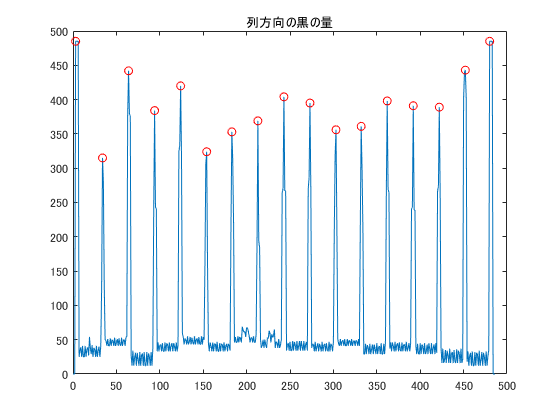

[maze_row_size,maze_col_size,maze_row_data,maze_col_data]=maze_data_get;

# 迷路情報取得関数

報を取得する迷路を選択

% [file,~] = uigetfile('*.*'); %情報を取得する迷路画像を選択
% orig_fig = file;

解析しやすいように画像を二値化

% maze_fig = imread(orig_fig); %迷路画像データを取り込み
% imshow(maze_fig)
% maze_fig = rgb2gray(maze_fig);%グレースケールに変換
% 
% binary_image = ~imbinarize(maze_fig);%二値化S
% [row_size,col_size] = size(binary_image);
% 
% %二値化前後で比較
% imshowpair(maze_fig,binary_image,'montage')

# 迷路画像の抽出

二値化データから迷路データの範囲を推定

% row_sum = sum(binary_image,2);
% col_sum = sum(binary_image,1)';
% 
% plot(row_sum);
% legend("row_sum")
% plot(col_sum);
% legend("col_sum")
% 
% [pks_row,locs_row] = findpeaks(row_sum,'MinPeakDistance',20);
% [pks_col,locs_col] = findpeaks(col_sum,'MinPeakDistance',20);
% 

行方向の迷路範囲特定

% row_th = pks_row > 300; %ピーク値のうち、閾値を超える箇所を抽出
% row_th_loc = locs_row(row_th ~= 0); %上で抽出した箇所の座標を取得
% row_th_min = min(row_th_loc);
% row_th_max = max(row_th_loc);

列方向の迷路範囲特定

% col_th = pks_col > 300; %ピーク値のうち、閾値を超える箇所を抽出
% col_th_loc = locs_col(col_th ~= 0); %上で抽出した箇所の座標を取得
% col_th_min = min(col_th_loc);
% col_th_max = max(col_th_loc);

ピーク値取得状態プロット

% row_vec = 0:1:row_size-1;
% col_vec = 0:1:col_size-1;
% plot(row_vec,row_sum,row_vec(locs_row),pks_row,'or')
% plot(col_vec,col_sum,col_vec(locs_col),pks_col,'or')

迷路範囲のみの画像を抽出

% binary_image_crop = ~imcrop(binary_image,[col_th_min-3 row_th_min-3 col_th_max-col_th_min+8 row_th_max-row_th_min+8]);
% imshow(binary_image_crop)
% title('Cropped Image')

# 迷路画像から迷路情報を取得

二値化データから迷路データの範囲を推定

% row_sum = sum(~binary_image_crop,2);
% col_sum = sum(~binary_image_crop,1)';
% 
% plot(row_sum);
% plot(col_sum);
% 
% [pks_row,locs_row] = findpeaks(row_sum,'MinPeakDistance',20);
% [pks_col,locs_col] = findpeaks(col_sum,'MinPeakDistance',20);

ピーク値取得状態プロット

% [crop_row_size,crop_col_size] = size(binary_image_crop); 
% row_vec_crop = 0:1:crop_row_size-1;
% col_vec_crop = 0:1:crop_col_size-1;   
% 
% plot(row_vec_crop,row_sum,row_vec(locs_row),pks_row,'or')
% title('行方向の黒の量')
% plot(col_vec_crop,col_sum,col_vec(locs_col),pks_col,'or')
% title('列方向の黒の量')

迷路の幅を確認(16*16のとき17*17)

% [maze_row_size,~] = size(pks_row);
% [maze_col_size,~] = size(pks_col);

迷路データを取得

% maze_row_data = [maze_col_size,maze_row_size-1];
% maze_col_data = [maze_col_size-1,maze_row_size];
% 
% %行方向壁情報取得
% for i = 1:maze_row_size
%     for n = 1:maze_col_size-1
%         temp = sum(~binary_image_crop(locs_row(i)+1,locs_col(n):locs_col(n+1)));        
%         maze_row_data(i,n) = temp;      
%     end    
% end
% 
% %列方向壁情報取得
% for i = 1:maze_row_size -1
%     for n = 1:maze_col_size
%         temp = sum(~binary_image_crop(locs_row(i):locs_row(i+1),locs_col(n)+1));        
%         maze_col_data(i,n) = temp;      
%     end    
% end
% 
% maze_row_data_temp = maze_row_data;
% maze_col_data_temp = maze_col_data;
% 
% plot(maze_row_data_temp)
% plot(maze_col_data)
% 
% maze_row_data = maze_row_data > 20;
% maze_col_data = maze_col_data > 20;
% 
% %原点を左下に（もとは左上）
% maze_row_data = flipud(maze_row_data);
% maze_col_data = flipud(maze_col_data);


取得した迷路データをプロット

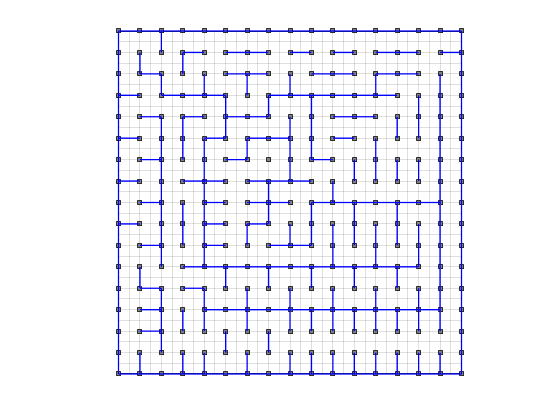

[ax] = maze_data_plot(maze_row_size,maze_col_size,maze_row_data,maze_col_data);

# 抽出された迷路情報をプロットする関数

% maze_step =  9;
% 
% [poleX,poleY] = meshgrid(0:maze_step:(maze_col_size-1)*maze_step,0:maze_step:(maze_row_size-1)*maze_step);
% plot(poleX,poleY,'s','MarkerSize',5,...
%     'MarkerEdgeColor',[0 0 0],...
%     'MarkerFaceColor',[0.5 0.5 0.5]);
% xlim([0 (maze_col_size-1)*maze_step])
% ylim([0 (maze_row_size-1)*maze_step])
% xticks(0:maze_step/2:(maze_col_size-1)*maze_step)
% yticks(0:maze_step/2:(maze_row_size-1)*maze_step)
% xticklabels({})
% yticklabels({})
% pbaspect([1 1 1])
% grid on
% 
% ax = gca;
% ax.TickLength = [0.0 0.0];
% hold on
% 
% %行方向壁情報プロット
% for i = 1:maze_row_size
%     for n = 1:1:(maze_col_size-1)
%        if maze_row_data(i,n) == 1
%            plot([n-1,n].*maze_step,[i-1,i-1].*maze_step,'b','LineWidth',1)
%        end
%     end
% end
% 
% %列方向壁情報プロット
% for i = 1:maze_row_size-1
%     for n = 1:1:(maze_col_size)
%        if maze_col_data(i,n) == 1
%            plot([n-1,n-1].*maze_step,[i-1,i].*maze_step,'b','LineWidth',1)
%        end
%     end
% end
% 
% hold off


マウスの画像を指定位置に指定角度でプロット

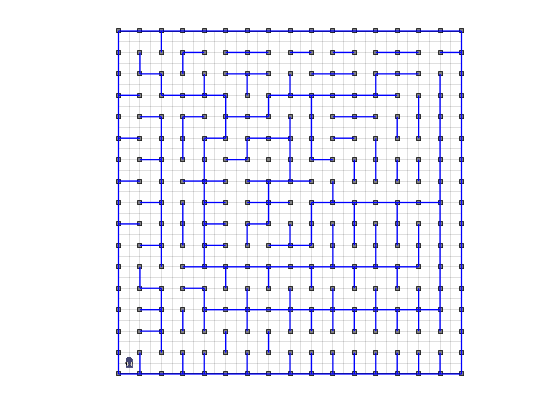

RGB = imread("manacov2.png");
[IND,map] = rgb2ind(RGB,8);
[ysize,xsize,~] = size(IND);
ycenter = 266; %マウス画像のタイヤ位置
[x,y]=meshgrid(-xsize/2:1:xsize/2-1,ycenter-ysize:1:ycenter-1);
z = x .* 0;
amap = uint8(IND ~= 3).*500;

%surfaceにマウス画像貼り付け
h = surface(x,y,z,IND,...
    'FaceColor','texturemap',...
    'EdgeColor','none',...
    'CDataMapping','direct',...
    'FaceAlpha','texturemap',...
    'AlphaDataMapping','none',...
    'AlphaData',amap);
colormap(map);

%surfaceを移動オブジェクト化
t = hgtransform('Parent',ax);
set(h,'Parent',t);

Rz = eye(4); 

    Txy = makehgtform('translate',[4.5 4.5 0]);
    % Z-axis rotation matrix
    Rz = makehgtform('zrotate',0);
    % Scaling matrix
    Sxy = makehgtform('scale',1/100);
    % Concatenate the transforms and
    % set the transform Matrix property
    set(t,'Matrix',Txy*Rz*Sxy);

 
 
 
 pause(1)


迷路データをシリアル通信用に変換

maze_data_to_serial(maze_row_size,maze_col_size,maze_row_data,maze_col_data);

9 3 9 5 1 5 5 1 5 1 5 1 5 5 1 7 
a c 2 9 0 5 5 0 1 4 5 0 5 5 0 3 
c 3 c 6 c 3 9 6 c 5 5 6 d 1 2 a 
9 4 1 5 3 c 6 9 3 9 5 5 1 2 a a 
c 3 a 9 6 9 5 6 a 8 5 1 2 a a a 
9 6 a a 9 6 9 3 a c 1 2 8 0 2 a 
c 3 8 6 c 1 4 6 c 1 2 a a a a a 
9 6 8 3 d 0 7 d 1 6 c 4 4 4 6 a 
c 3 a a d 0 7 9 2 9 3 9 3 9 3 a 
9 6 a a d 2 9 6 e a a a a a a a 
8 3 8 6 d 4 4 5 5 6 c 6 c 6 a a 
a c 0 5 3 9 3 9 3 9 3 9 3 9 2 a 
8 7 8 3 c 6 c 6 c 6 c 6 c 6 e a 
8 7 a a 9 3 9 3 b b b b b b b a 
8 3 8 0 2 8 2 8 0 0 0 0 0 0 0 2 
e c 6 e c 6 c 6 e e e e e e e e 
